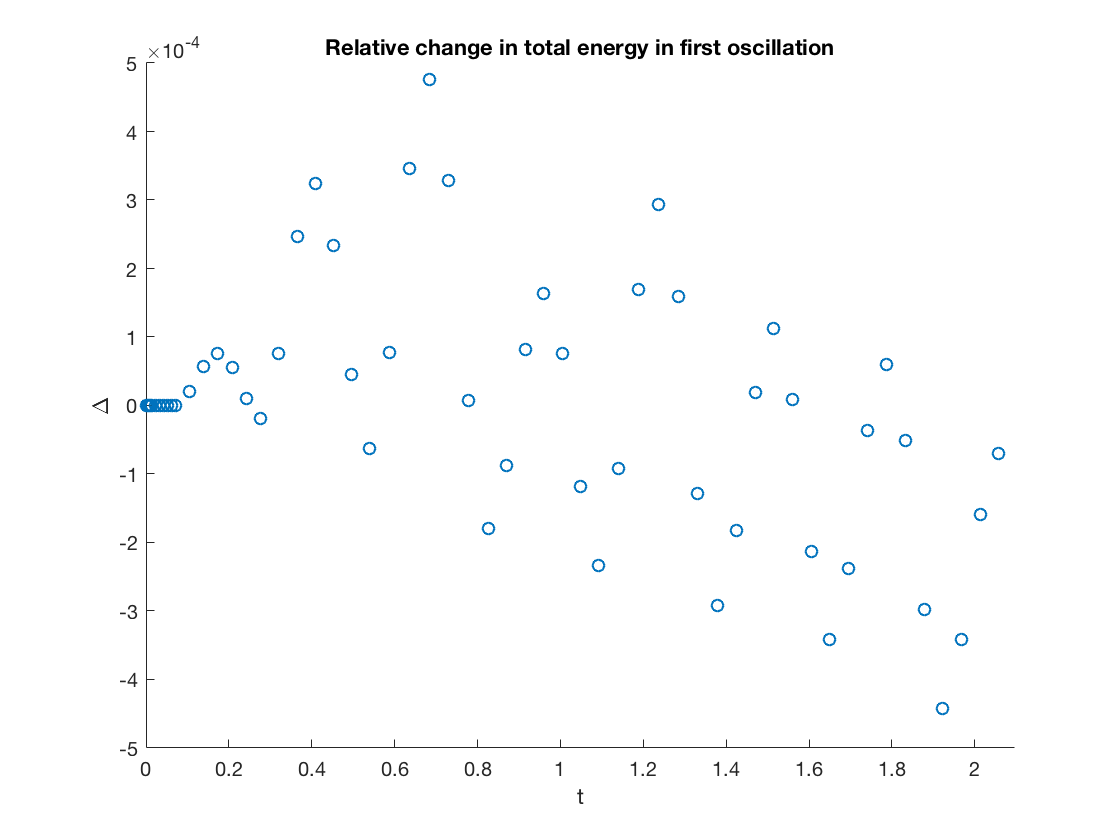

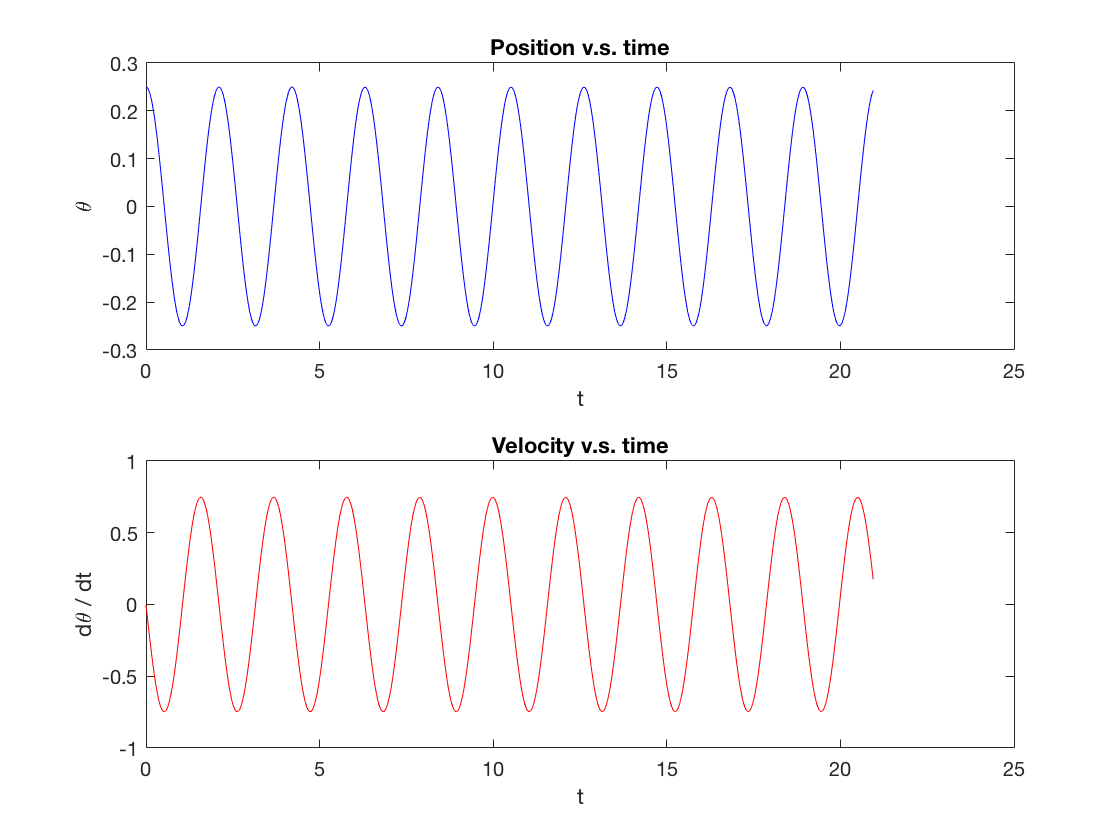

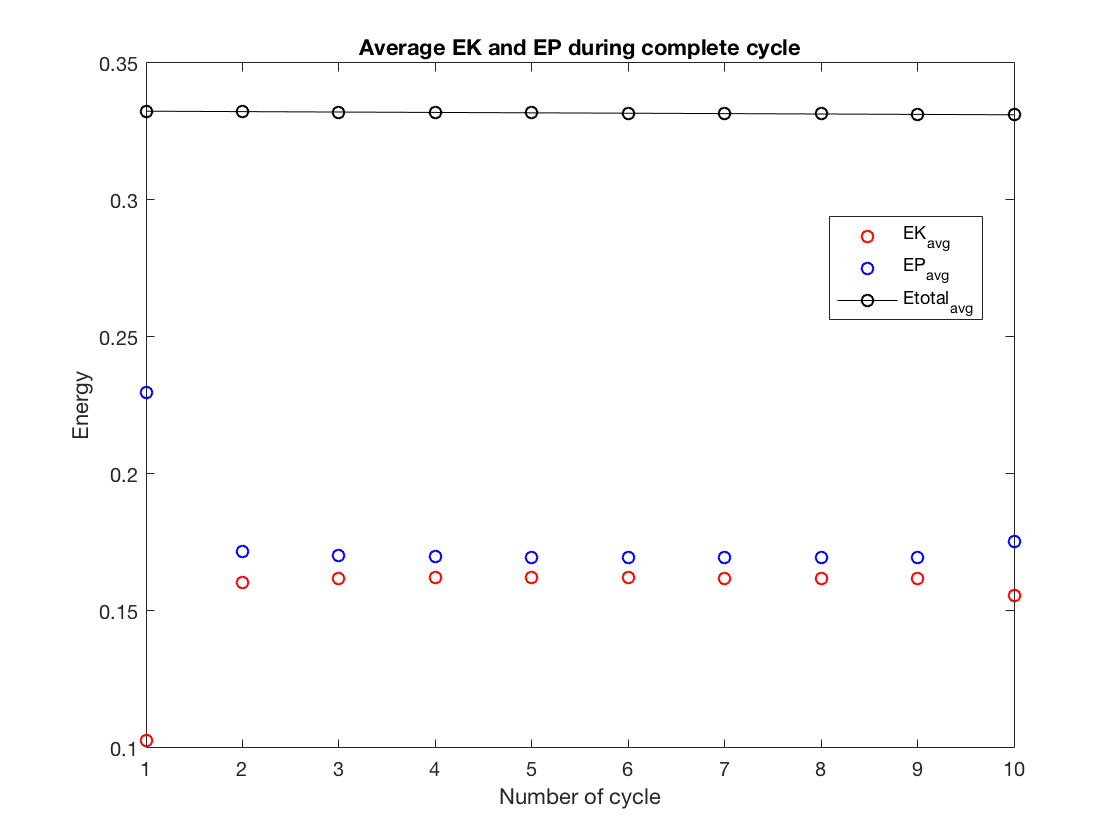

close all

[T,sol] = pendulum1(3,0.25,0);

## **Energy Consevation**

(a) Calculate relative change in total energy during one cycle: Delta_n = (En - E0) / E0

We plotted Delta_1, which is relative energy change in **first oscillation**. As shown in the plot, it is not uniformly small during one cycle. 

(b) Plot theta v.s. time, d_theta v.s. time

(c) To better display EK_avg and EP_avg, with total E, we choose Ep = 0 on the bottom of the trajectory of pendulum. 

We find that the total energy is conservative.

(d) Plot phase space for different initial condition.

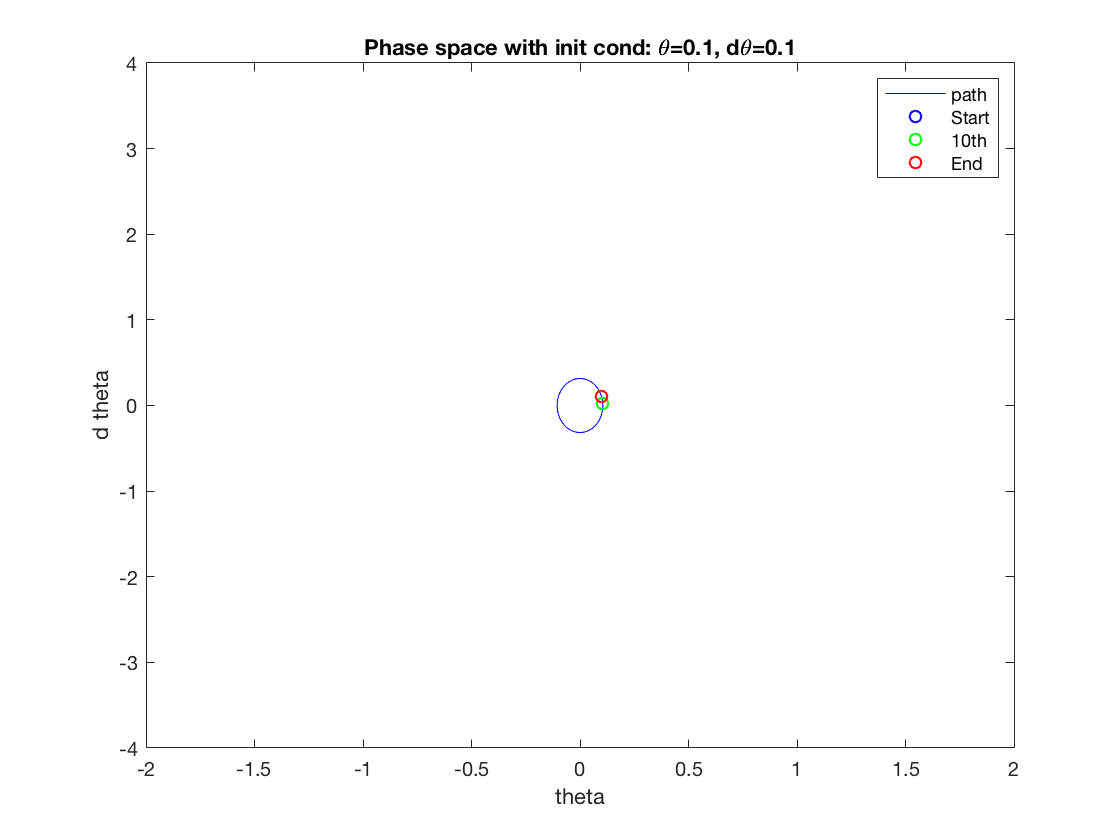

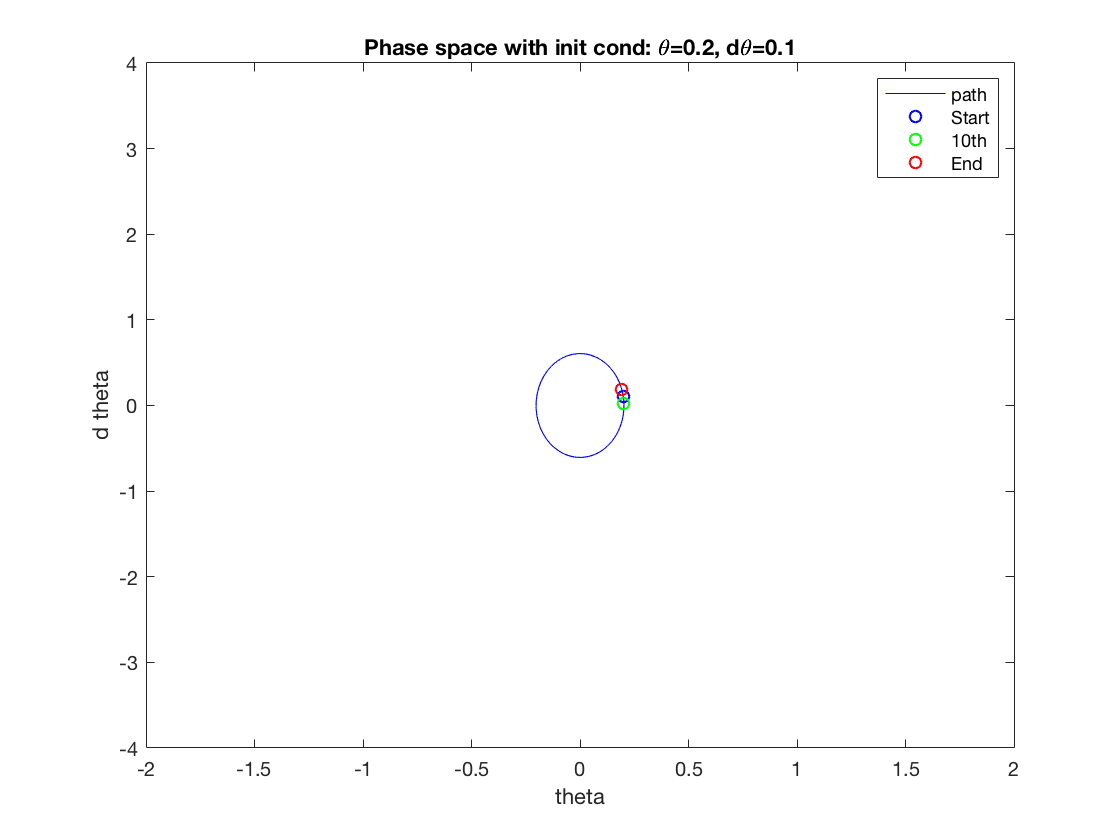

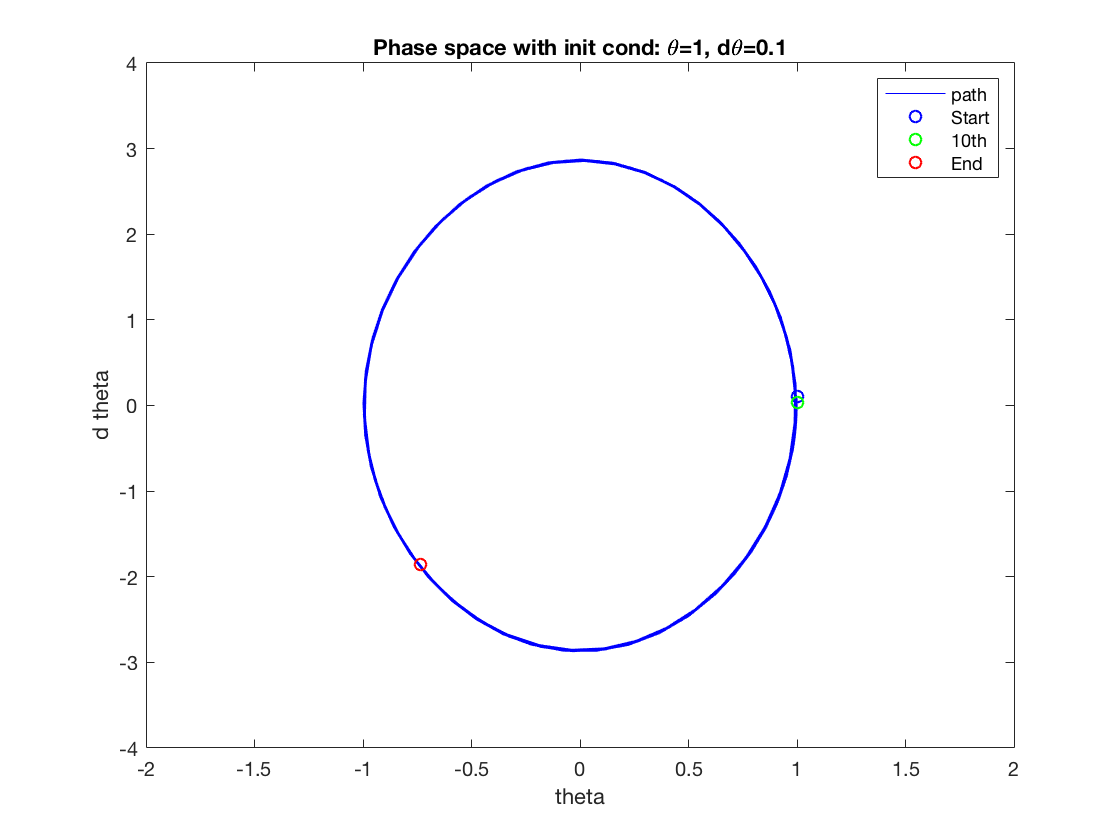

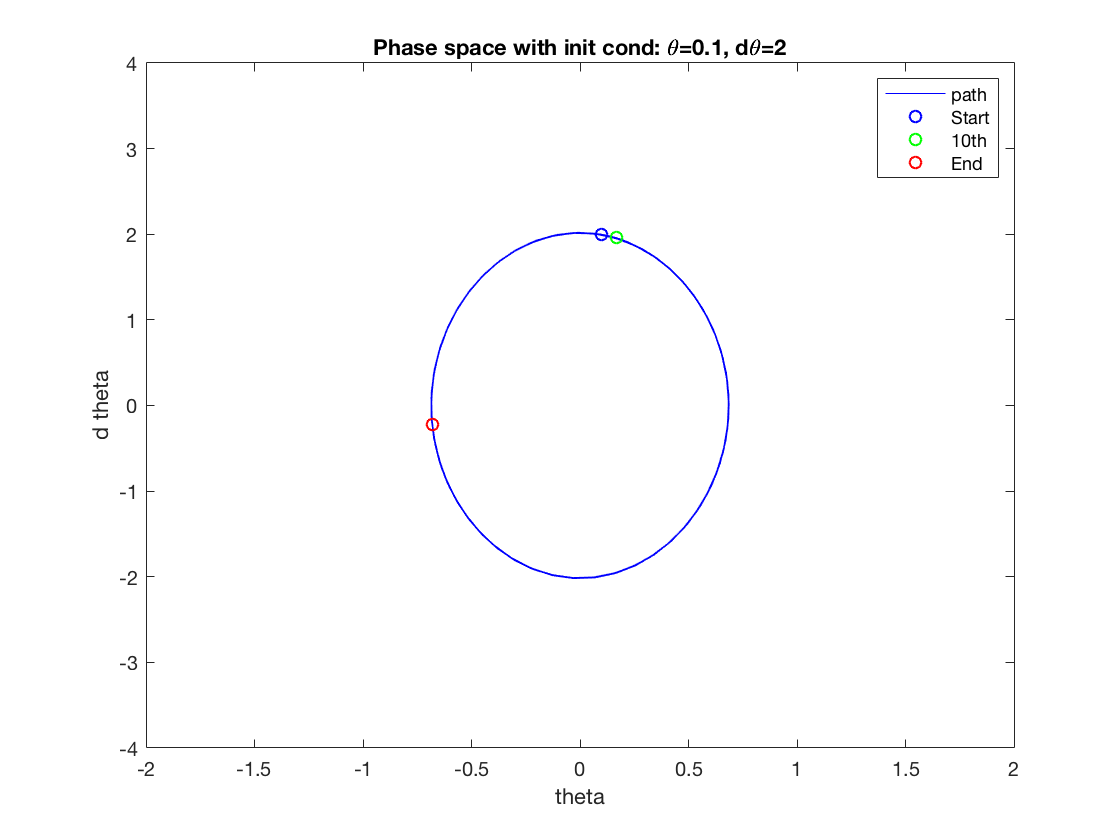

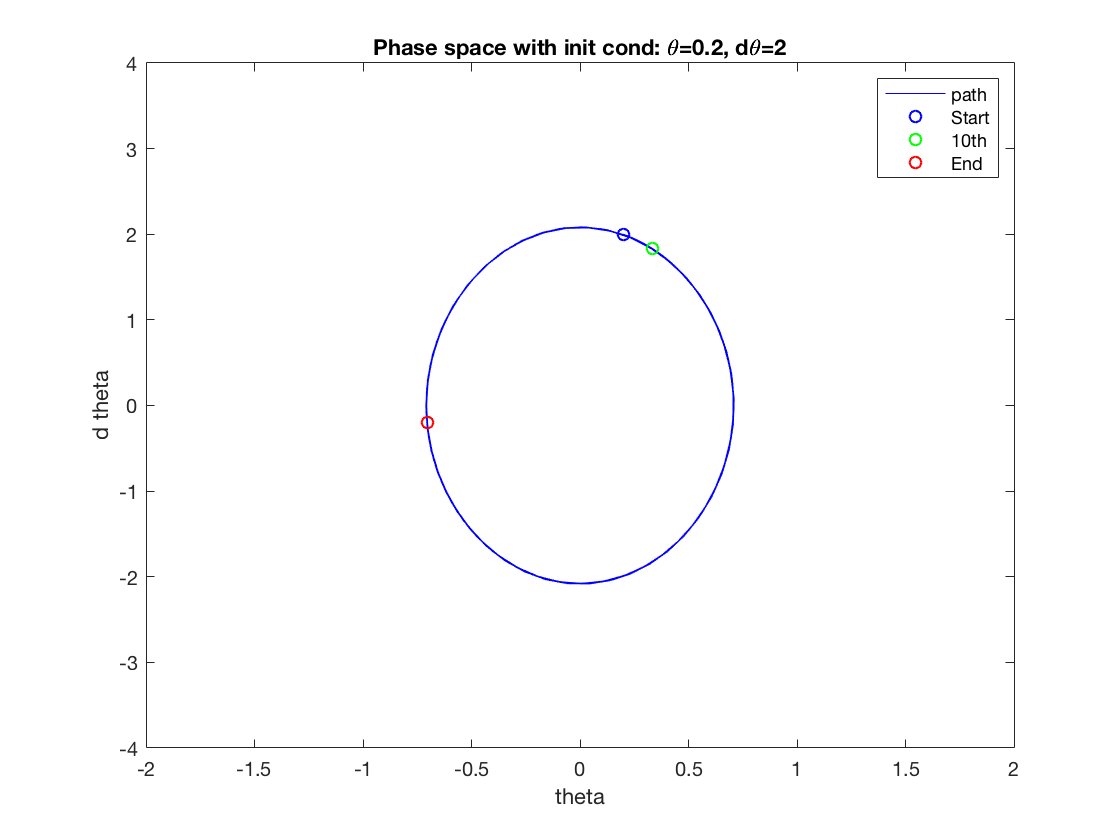

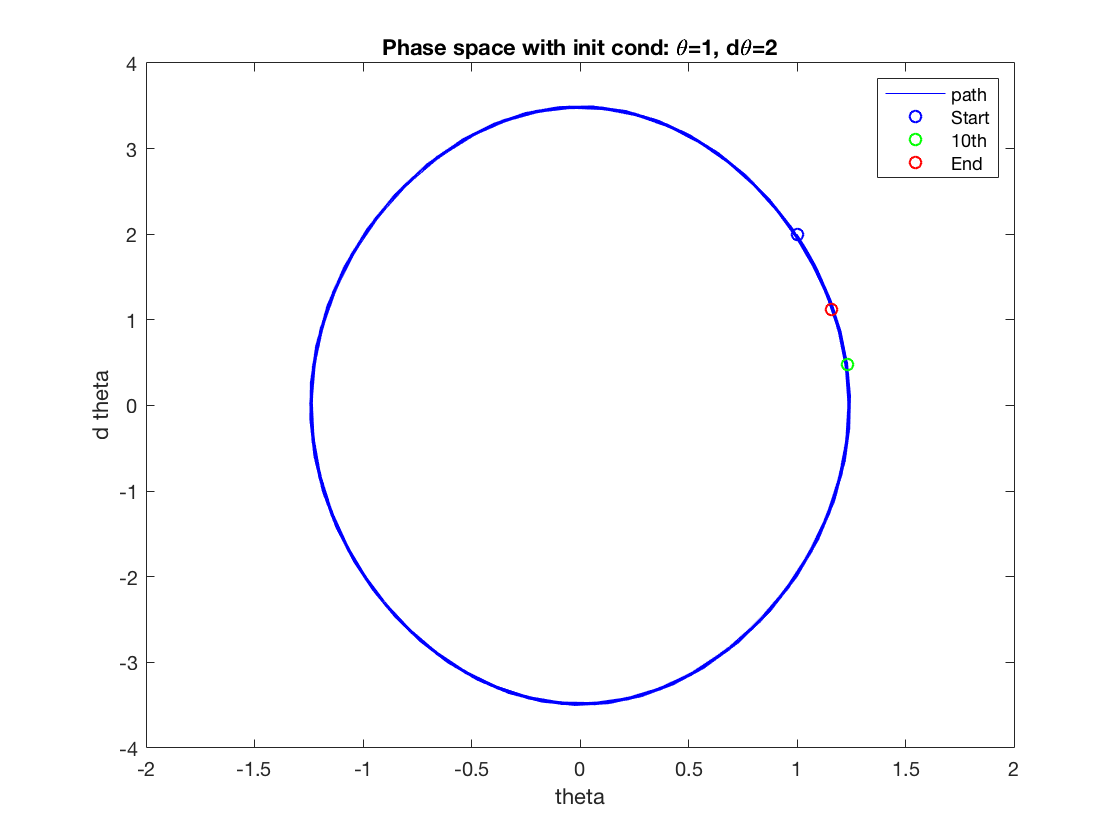

init_set = [
    0.1    0.1;
    0.2    0.1;
    1      0.1;
    0.1    2;
    0.2    2;
    1      2;
    ];

for i=1:6
    theta0 = init_set(i,1);
    dtheta0 = init_set(i,2);
    [T,sol] = pendulum1(3,theta0,dtheta0,0);
    figure
    plot(sol(:,2),sol(:,3),'b',sol(1,2),sol(1,3),'bo',sol(10,2),sol(10,3),'go',sol(end,2),sol(end,3),'ro')
    title(['Phase space with init cond: \theta=' num2str(theta0) ', d\theta=' num2str(dtheta0)])
    legend('path','Start','10th','End')
    xlim([-2,2])
    ylim([-4,4])
    xlabel('theta')
    ylabel('d theta')
end

The shape of the path is ellipse, and initial condition determines its size. The direction is always clockwise.